fname = 'Pilot2_results.json';
fid = fopen(fname);
raw = fread(fid,inf);
str = char(raw');
fclose(fid);
result = jsondecode(str);

for j = 1:length(result.Batches)
    for i = 1:length(result.Batches(j).Trials)
        trialNumber = result.Batches(j).Trials(i).TrialNumber;
        DisplayTarget = result.Batches(j).Trials(i).DisplayTarget;
        video = result.Batches(j).Trials(i).Video;
        mouseResponse = result.Batches(j).Trials(i).Response.MouseResponse;
        responseTime = result.Batches(j).Trials(i).Response.ResponseTime;
        disp(j + ", " + trialNumber + ", " + DisplayTarget + ", " + video + ", " + mouseResponse + ", " + responseTime)
    end
end

1, 1, VR, beep_video9, 0, 3.8321
1, 2, VR, beep_video11, 0, 3.3653
1, 3, VR, beep_video5, 1, 1.7252
1, 4, VR, beep_video11, 0, 3.509
1, 5, VR, beep_video13, 1, 2.075
1, 6, VR, beep_video12, 0, 3.8854
1, 7, VR, beep_video6, 1, 2.2089
1, 8, VR, beep_video13, 1, 2.4028
1, 9, VR, beep_video8, 0, 2.1335
1, 10, VR, beep_video10, 1, 3.5319
1, 11, VR, beep_video12, 1, 2.321
1, 12, VR, beep_video8, 1, 3.0475
1, 13, VR, beep_video7, 1, 2.2957
1, 14, VR, beep_video5, 1, 1.9666
1, 15, VR, beep_video12, 1, 2.3487
1, 16, VR, beep_video9, 0, 2.4837
1, 17, VR, beep_video8, 0, 2.2026
1, 18, VR, beep_video5, 0, 2.6907
1, 19, VR, beep_video9, 1, 3.2534
1, 20, VR, beep_video10, 1, 2.795
1, 21, VR, beep_video13, 1, 2.1927
1, 22, VR, beep_video6, 1, 1.984
1, 23, VR, beep_video6, 1, 3.0137
1, 24, VR, beep_video7, 0, 2.9042
1, 25, VR, beep_video11, 1, 4.9408
1, 26, VR, beep_video10, 0, 2.0286
1, 27, VR, beep_video7, 1, 3.245
2, 1, VR, violin_video9, 1, 3.9443
2, 2, VR, violin_video9, 0, 3.0887
2, 3, VR, violi

HistResults = zeros(9,2,2);


participant = 2;
for j = 1
    for i = 1:length(result.Batches(j).Trials)
        video = result.Batches(j).Trials(i).Video;
        response = result.Batches(j).Trials(i).Response.MouseResponse;
        regexPattern = "\d{1,2}";
        videoNumberString = regexp(video,regexPattern,'match');
        videoNumber = str2num(videoNumberString{1});
        videoNumber = videoNumber - 4;
        
        if (response == 0)
            HistResults(videoNumber, j, participant) = HistResults(videoNumber, j, participant) + 1;
        end
    end
end
for j = 2
    for i = 1:length(result.Batches(j).Trials)
        video = result.Batches(j).Trials(i).Video;
        response = result.Batches(j).Trials(i).Response.MouseResponse;
        regexPattern = "\d{1,2}";
        videoNumberString = regexp(video,regexPattern,'match');
        videoNumber = str2num(videoNumberString{1});
        videoNumber = videoNumber - 4;
        
        if (response == 0)
            HistResults(videoNumber, j, participant) = HistResults(videoNumber, j, participant) + 1;
        end
    end
end

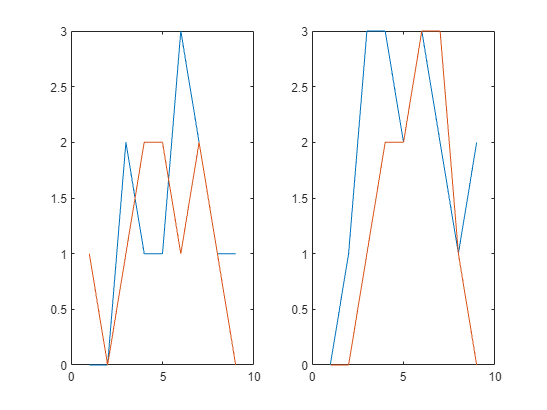

subplot(1,2,1); plot(HistResults(:,1,1)); hold on; plot(HistResults(:,1,2)); hold off
subplot(1,2,2); plot(HistResults(:,2,1)); hold on; plot(HistResults(:,2,2)); hold off